# Solving the Replicator-Mutator Equation by Forward Euler

The following code applies the result from Rosenbloom et al (Mutation Rate Evolution in Replicator Dynamics Benjamin Allen) that Invasion fitness of the mutation rate $u$ into a population with trait distribution $\phi(\tilde{x})$ is $\lambda_{\max}(Q(u)F(\tilde{x}))-\phi(\tilde{x})$, where

- $Q(u)$ is the "spread matrix," with $ij^{\textrm{th}$ entry the probability an individual with trait $i$ while have an offspring of trait $j$.

- $F(\vec{x})$ is the "growth matrix," which is diagonal with $ii^{\textrm{th}}$ entry the fitness of trait $i$, given $\vec{x}$.

Under constant selection, where the fitness doesn't vary with the trait distribution or time, the equilibrium distribution will simply be the eigenvector corresponding to the maximum eigenvalue, which will conveniently be the average fitness. Thus, a single graph of the maximum eigenvalues is sufficient to tell how evolution will evolve (in the direction that increases this value). 

The code has the following inputs. The first two are more significant, so are given in their own blocks, while the second appear in the main computation's block. 

- Local Mutation Kernel

- Fitness Function

- Discretization Size

- Query Mutation Rates

All the code sections can be run by pressing F5, then individual changes can be made to any of the model inputs, and the main computation can be re-executed to see how this changes the results. 

## Initialize

clear; clc; % clear stored variables
close all % closes open figures

## Local Mutation Kernel

Here we define the local mutation kernel, which govens how offspring mutate for a given mutation rate $u$. 

This also defines $Q(u)$, given by how mutation beyond the boundaries is handled. The code for this is given in functions defined at the end of the file (as Matlab requires for local functions). 

To better visualize this, some rows of $Q(u)$ are plotted. 

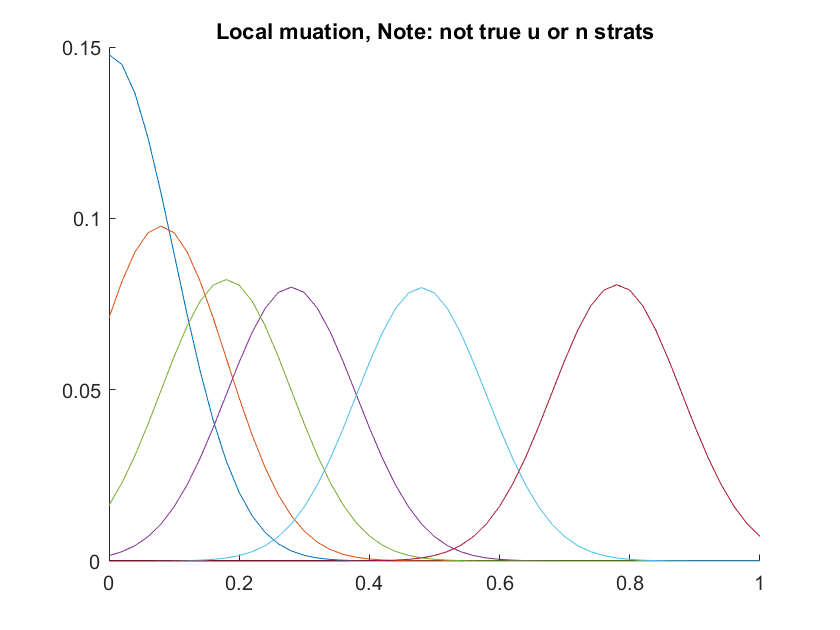

normal = @(xs, strat, u) normpdf(xs,strat,u); %exp(((xs-mean)/sigma).^2/2)/(sigma*sqrt(2*pi));
peak   = @(xs, strat, u) interp1([-10, strat-u/2, strat, strat+u/2, 10], [0, 0, 1, 0, 0], xs);
flat   = @(xs, strat, u) double(abs(xs-strat) < u/2);

spread_funct = normal;
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
% options: trunc_spread_matrix, accum_spread_matrix, circ_spread_matrix,
% integ_trunc_spread_matrix, integ_accum_spread_matrix, unif_spread_matrix

test_n = 51;
test_spread = spread_matrix_funct(0.1,test_n);
figure
hold on
to_show = [1, 5, 10, 15, floor(0.2*test_n), floor(0.5*test_n), floor(0.8*test_n)];
for i=1:length(to_show)
    plot(linspace(0,1,test_n), test_spread(:, to_show(i)))
end
title("Local muation, Note: not true u or n strats")
hold off % note some are higher / lower because of normalization

## Fitness

Here we define the fitness we want to investigate. 

To help visualize this, a plot is given, though not with the true discretization. 

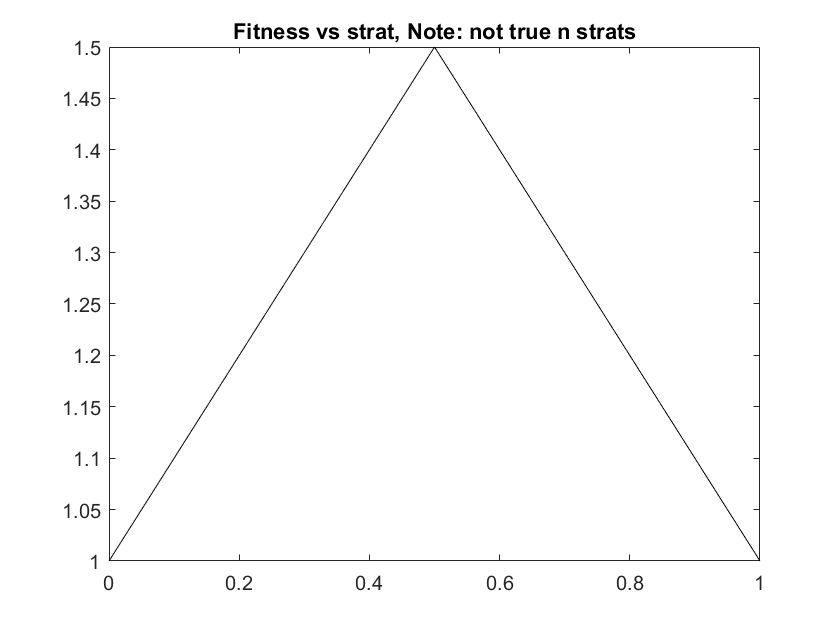

indic = @(x,a,b) x>a && x<b;

min_fit     = @(strats) 1+min(strats, 1-strats);
sin_fit     = @(strats) 2+sin(2*pi*(strats));
cos_fit     = @(strats) 2+cos(2*pi*strats);
scrunch_sin = @(strats) arrayfun(@(x) 2+sin(6*pi*x*indic(x,1/3,2/3)), strats);
two_steps   = @(strats) arrayfun(@(x) 1+2*indic(x,0,0.2)+2.2*indic(x,1-0.025,1), strats);

twin_steps_funct = @(w,g,h,strats) arrayfun(@(x) ...
    1+h*indic(x,1/2-g/2-w,1/2-g/2)+h*indic(x,1/2+g/2,1/2+g/2+w), strats);
twin_steps = @(strats) twin_steps_funct(0.2, 0.4, 2, strats); % in circ?

three_steps_funct = @(w,d,h, strats) arrayfun(@(x) 1 + h*indic(x,0.5-d-3*w,0.5-d-w) + ...
    1*indic(x,0.5-w,0.5+w) + h*indic(x,0.5+d+w,0.5+d+3*w), strats);
three_steps = @(strats) three_steps_funct(0.05, 0.1, 0.9, strats);

centered_two_steps_funct = @(w1,h1,w2,h2, strats) arrayfun(@(x) ...
    1 + h1*indic(x,(1-w1-w2)/3, (1-w1-w2)/3+w1) + ...
    h2*indic(x,1-(1-w1-w2)/3-w2, 1-(1-w1-w2)/3), strats);
centered_two_steps = @(strats) centered_two_steps_funct(0.2,3,0.025,3.2, strats);

% not functions, so they don't change each time fitness is called
rand_fit_1 = @(strats) 1+interp1(linspace(0,1,10),rand(1,10), strats); 
rand_fit_2 = @(strats) 1+interp1([0, sort(rand(1,10-2)), 1], rand(1,10), strats); 

%load('increasing with MR')
%fitness = @(t,dist) interp1(linspace(0,1,51), ...
%    fitness_leading_to_increasing_curve, strats);



HD = @(val) [[val-1, 2*val]; [0, val]];
T = 4; R = 3; P = 2; S = 1; % need T>R>P>S for PD
PD = [[R, S]; [T, P]];
coordination = eye(2);
assurance = [[2, 0]; [0, 1]]; % ~ SH
AC = [[0, 1]; [1, 0]]; % anti-coordination
SH = [[4, 1]; [3, 2]]; % stag hunt

game = SH;
a = game(1,1); b = game(1,2); c = game(2,1); d = game(2,2);
payoff_to = @(y,x) exp(a*x*y + b*(1-x)*y+c*x*(1-y) + d*(1-x)*(1-y));
game_fit = @(t, dist,strats) arrayfun(@(x) payoff_to(x,strats*dist), strats);



fitness = @(t,dist,strats) min_fit(strats);

test_n = 101;
figure
plot(linspace(0,1,test_n), fitness(0,zeros(test_n,1),linspace(0,1,test_n)), 'k')
title("Fitness vs strat, Note: not true n strats")

## Show one run over time

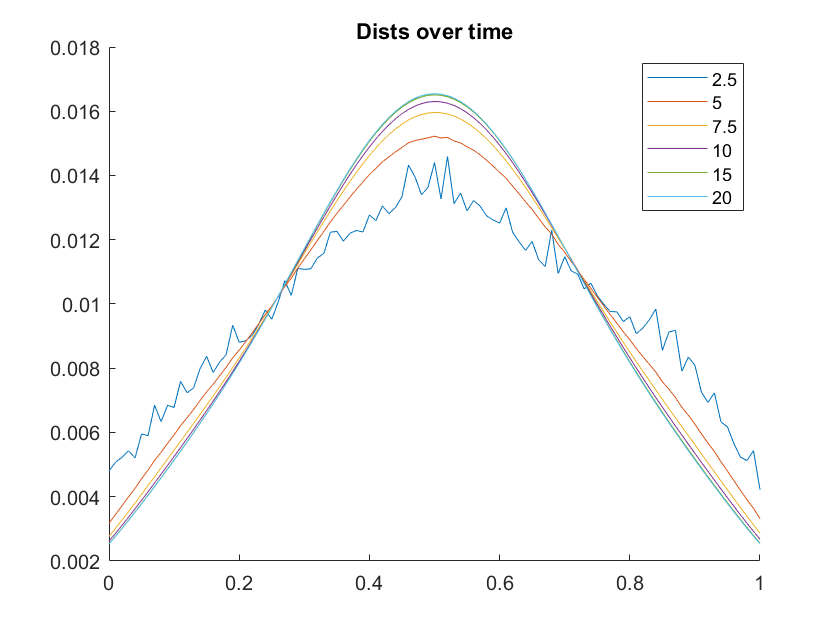

n_strats = 101; 
strats = linspace(0,1,n_strats);
u = 0.1;
delta_t = 0.01;
sample_pts  = [250, 500, 750, 1000, 1500, 2000];

dist_record = -1*ones(n_strats,length(sample_pts));
avg_strats  = zeros(1,max(sample_pts));
avg_fit     = zeros(1,max(sample_pts));
    
dist = init(n_strats);
for i=1:max(sample_pts)
    % Store values
    if ismember(i, sample_pts)
        first_non_empty_col = find(dist_record(1, :)==-1, 1, 'first'); 
        dist_record(:,first_non_empty_col) = dist;
        %fprintf("sum(dist) = %f \n", sum(dist)) % should always = 1
    end
    avg_strats(i) = strats*dist;
    avg_fit(i) = sum(growth*dist);
    
    % Update growth matrix and trait distribution
    growth = zeros(n_strats,n_strats);
    growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist,strats);
    dist = advance(dist, spread_matrix_funct(u,n_strats), growth, delta_t);
end


figure
hold on
for blah=1:length(sample_pts)
    plot(strats, dist_record(:,blah));
end
legend(arrayfun(@(x) num2str(x), sample_pts*delta_t, 'UniformOutput', false))
title("Dists over time")
hold off

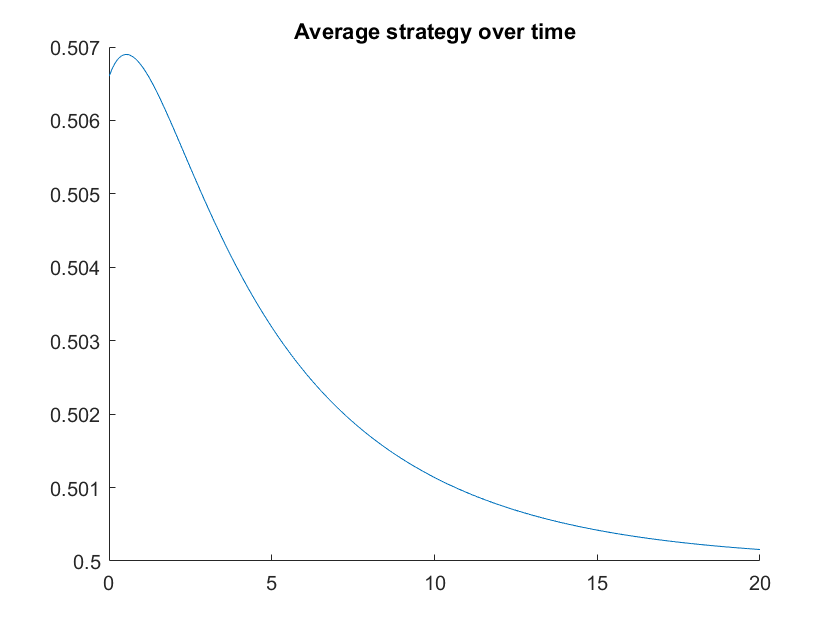


figure
hold on
plot(delta_t*(1:max(sample_pts)), avg_strats)
title("Average strategy over time")
hold off

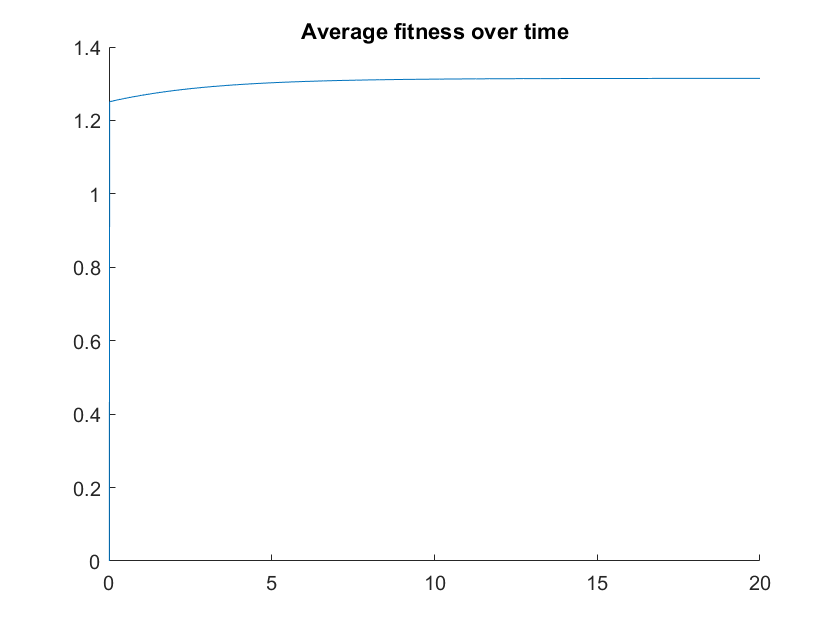

figure
hold on
plot(delta_t*(1:max(sample_pts)), avg_fit)
title("Average fitness over time")
hold off

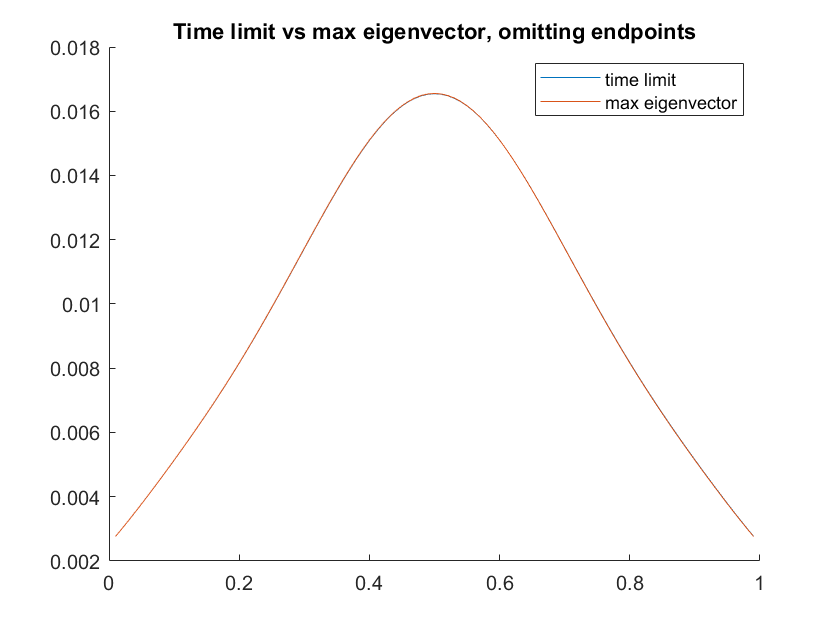


% Comparison with Spectral analysis, only applies for fixed fitness, useful to confirm results
if true
    A = spread_matrix_funct(u,n_strats)*growth; 
    [V,D] = eig(A);
    [max_eig, loc] = max(diag(D));
    stable_dist = abs(V(:,loc))/sum(abs(V(:,loc)));
    phi = growth*stable_dist;
    %fprintf("Maximum eigenvalue for MR %f is %f. \n", u, max_eig)
    
    figure
    hold on
    plot(strats(2:(end-1)), dist(2:(end-1)))
    plot(strats(2:(end-1)), stable_dist(2:(end-1)))
    legend("time limit", "max eigenvector")
    title("Time limit vs max eigenvector, omitting endpoints")
    hold off
end

## Run many times to verify unique solution

n_strats = 101; 
strats = linspace(0,1,n_strats);
u = 0.1;
delta_t = 0.01;
n_trials = 10;
n_steps = 1500;

final_dists = zeros(n_strats, n_trials);
for i=1:n_trials
    if mod(10*i/n_trials, 1) == 0 % helpful for long runs
        fprintf("Completed trial %.0f. \n", i)
    end
    
    % generate initial dist
    dist = init(n_strats);
    dist(80) = 100;
    dist = dist/sum(dist);
    
    % advance n_steps times
    for j=1:n_steps
        growth = zeros(n_strats,n_strats);
        growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(j*delta_t, dist,strats);
        dist = advance(dist, spread_matrix_funct(u,n_strats), growth, delta_t);
    end
    
    % record it
    final_dists(:,i) = dist;
end

Completed trial 1. 
Completed trial 2. 
Completed trial 3. 
Completed trial 4. 
Completed trial 5. 
Completed trial 6. 
Completed trial 7. 
Completed trial 8. 
Completed trial 9. 
Completed trial 10. 


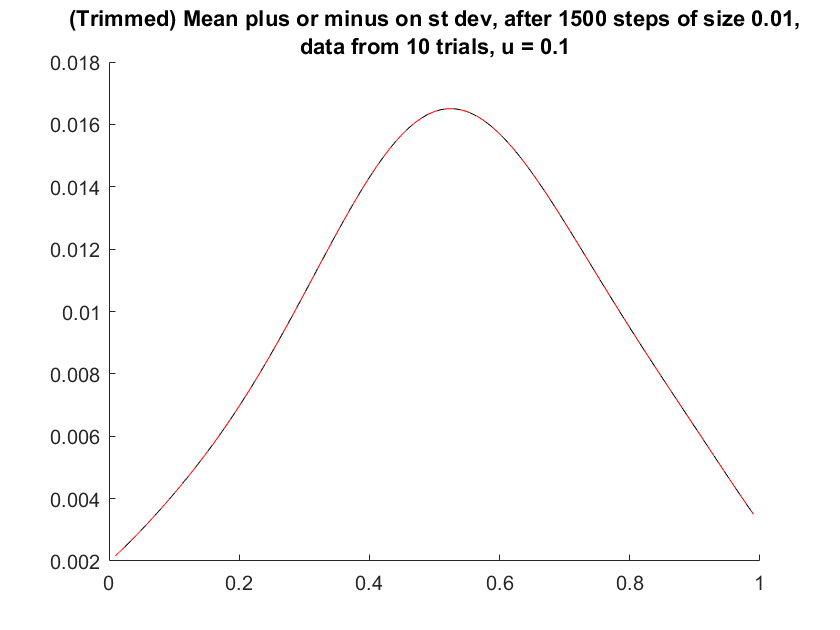


means = mean(final_dists, 2);
stdevs = std(final_dists, 0, 2);

figure
hold on
plot(strats(2:(end-1)), means(2:(end-1))+stdevs(2:(end-1)), '--r')
plot(strats(2:(end-1)), means(2:(end-1)), '-k')
plot(strats(2:(end-1)), means(2:(end-1))-stdevs(2:(end-1)), '--r')
title(["(Trimmed) Mean plus or minus on st dev, after " + n_steps + ...
    " steps of size " + delta_t + ",","data from " + n_trials + ...
    " trials, u = " + u])
hold off

## Max eigenvalue of Q(u)F(x) vs avg fitness at limit

Should put in a loop so many resident MR's are checked. 

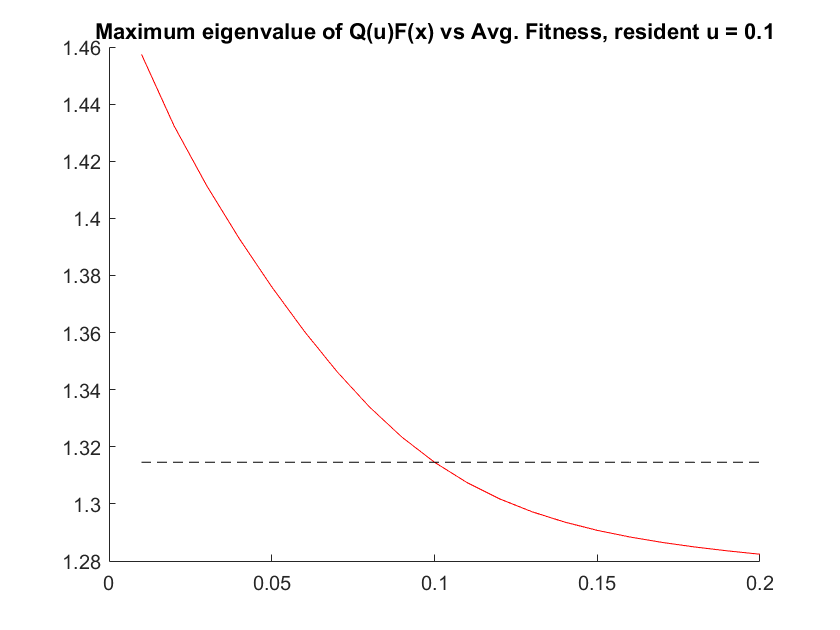

n_strats = 101;

query_us   = 0.01*(1:20);
resident_u = 0.1;
delta_t    = 0.01;
n_steps    = 5000; % far enough for distribution to stabilize? Could also write with a while loop

spread = spread_matrix_funct(resident_u,n_strats);
dist = init(n_strats);
dist(70) = 10;
dist = dist/sum(dist);
for i=1:n_steps
    growth = zeros(n_strats,n_strats);
    growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist,strats);
    dist = advance(dist, spread, growth, delta_t);
end
avg_fitness = sum(growth*dist);

max_eigs = zeros(size(query_us));
for j=1:length(query_us)
    [V,D] = eig(spread_matrix_funct(query_us(j),n_strats)*growth);
    [max_eig, loc] = max(diag(D));
    max_eigs(j) = max_eig;
end

figure
hold on
plot(query_us, max_eigs, 'r');
plot(query_us, avg_fitness*ones(size(query_us)), '--k');
%plot(query_us(i)*ones(1,5), linspace(min_val,max_val,5), 'k'); % vertical line
title("Maximum eigenvalue of Q(u)F(x) vs " + ...
    "Avg. Fitness, resident u = " + resident_u)
hold off

# Time Varying Fitness

Also could have MR a function of time, e.g. annealing in particle swarm optimization. 

Don't need a separate block, could just change fitness block. 

w = 0.1;
period = 1;
fitness = @(t,dist,strats) normpdf(strats, (1+sin(2*pi*t/period))/2, w);

u = 0.5;

n_strats = 101; 
strats = linspace(0,1,n_strats);
delta_t = 0.01;
n_steps = 10000;

avg_strats  = zeros(1,n_steps);
avg_fit     = zeros(1,n_steps);
init_dist = init(n_strats);
dist = init_dist;
tic
for i=1:n_steps
    % Update growth matrix and trait distribution
    growth = zeros(n_strats,n_strats);
    growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist, strats);
    
    avg_strats(i) = strats*dist;
    avg_fit(i) = sum(growth*dist);
    
    dist = advance(dist, spread_matrix_funct(u,n_strats), growth, delta_t);
end
toc

Elapsed time is 8.549991 seconds.


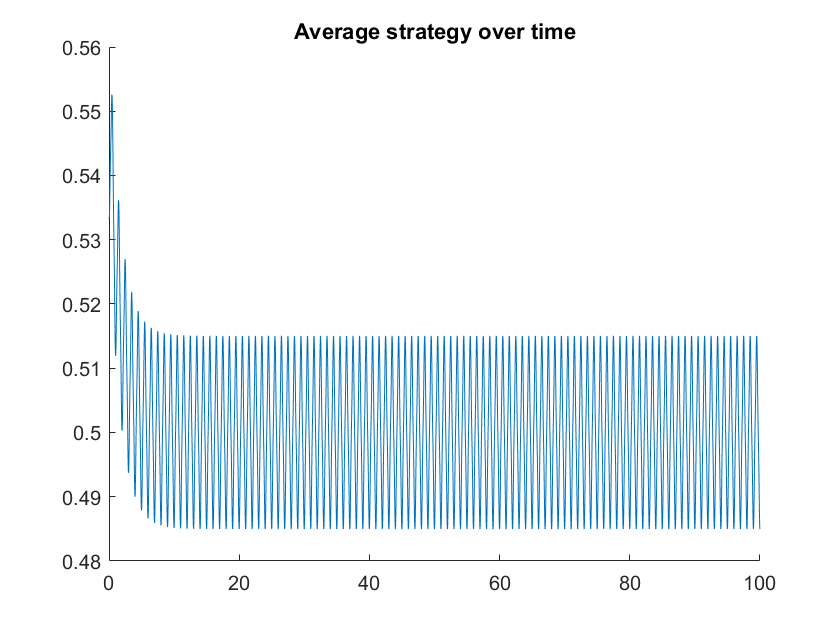


figure
hold on
plot(delta_t*(1:n_steps), avg_strats)
title("Average strategy over time")
hold off

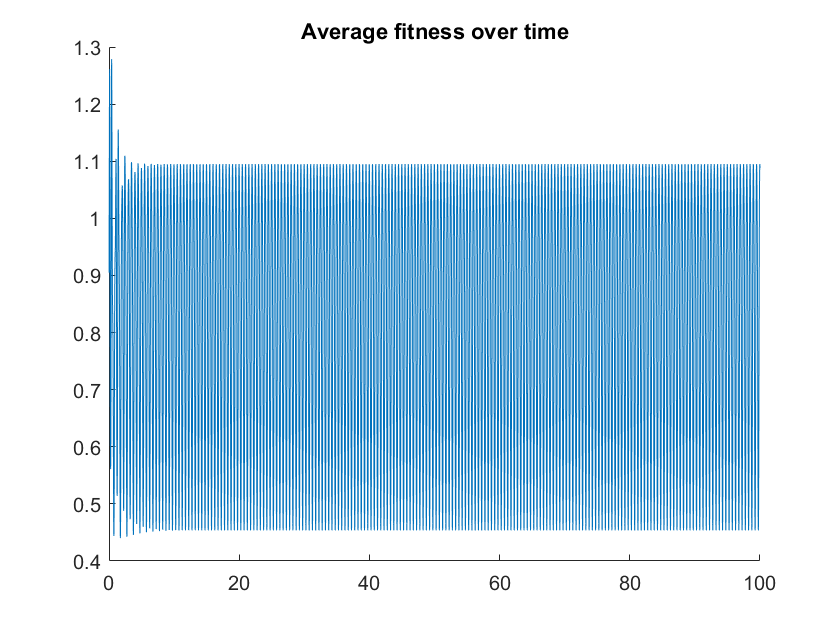


figure
hold on
plot(delta_t*(1:max(n_steps)), avg_fit)
title("Average fitness over time")
hold off


fprintf("Avg. fitness = " + mean(avg_fit(floor(end/2):end))) 

Avg. fitness = 0.82078

## Time varying fitness, plot avg fitness vs MR

w = 0.1;
period = 5;
fitness = @(t,dist,strats) normpdf(strats, (1+sin(2*pi*t/period))/2, w);

us = 0.1*(1:10);

n_strats = 101; 
strats = linspace(0,1,n_strats);
delta_t = 0.01;
n_steps = 10000;

avg_avg_fit = zeros(size(us));
std_avg_fit = zeros(size(us));
init_dist = init(n_strats);
for j=1:length(us)
    avg_fit     = zeros(1,n_steps);
    tic
    dist = init_dist;
    for i=1:n_steps
        % Update growth matrix and trait distribution
        growth = zeros(n_strats,n_strats);
        growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist, strats);
        
        avg_fit(i) = sum(growth*dist);
        
        dist = advance(dist, spread_matrix_funct(us(j),n_strats), growth, delta_t);
    end
    
    if false
        figure
        hold on
        plot(delta_t*(1:max(n_steps)), avg_fit)
        title("Average fitness over time")
        hold off
    end
    
    avg_avg_fit(j) = mean(avg_fit(floor(0.5*end):end)); % want to capture all cycles, but not setup
    std_avg_fit(j) = std(avg_fit(floor(0.5*end):end));
    toc
end

Elapsed time is 10.846132 seconds.
Elapsed time is 13.119174 seconds.
Elapsed time is 14.594565 seconds.
Elapsed time is 18.821868 seconds.
Elapsed time is 15.454728 seconds.
Elapsed time is 12.228752 seconds.
Elapsed time is 13.360821 seconds.
Elapsed time is 10.586863 seconds.
Elapsed time is 7.337393 seconds.
Elapsed time is 7.130012 seconds.


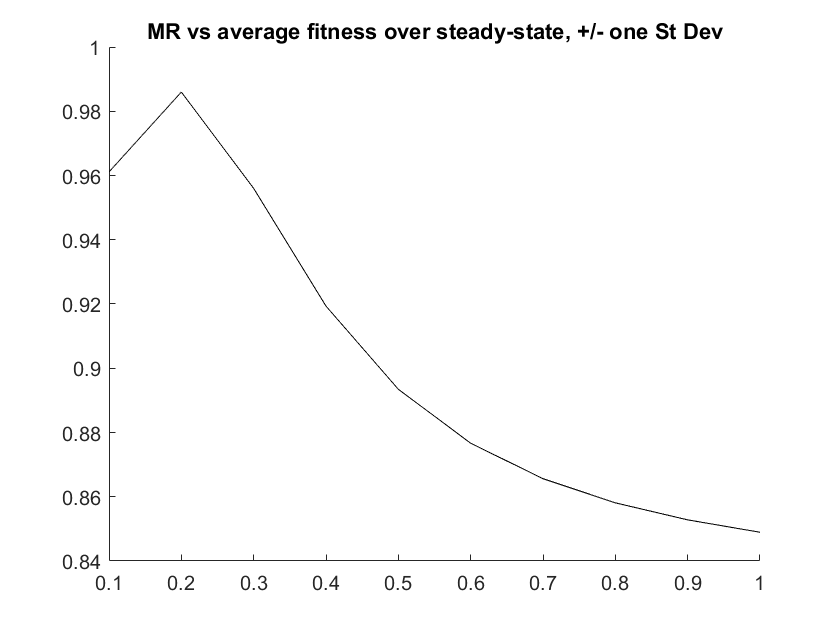


figure
hold on
%plot(us, avg_avg_fit+std_avg_fit, 'b--')
plot(us, avg_avg_fit, 'k')
%plot(us, avg_avg_fit-+std_avg_fit, 'b--')
hold off
title("MR vs average fitness over steady-state, +/- one St Dev")

# Direct competition of two MR's

This shows one run of two MR's, initialized at the same time.  

One could also run many times to verify this outcome.

delta_t  = 0.01;
sample_pts = [1, 500, 1000, 2500, 5000, 10000, 15000, 20000, 25000];
n_steps = max(sample_pts);
n_strats = 101;
strats   = linspace(0,1,n_strats);
v = 0.05; % initial proportion of invaders

u_res = 0.4;
u_inv = 0.01; % or us = 0.05*(1:10), u1 = us(i); u2 = u1 + delta_u

dist1 = init(n_strats);
dist2 = init(n_strats);
dist = [(1-v)*dist1; v*dist2]; % so sum = 1

spread_res = spread_matrix_funct(u_res,n_strats);
spread_inv = spread_matrix_funct(u_inv,n_strats);
spread = blkdiag(spread_res, spread_inv);

% recording matrices
dist1_record = -1*ones(n_strats,length(sample_pts));
dist2_record = -1*ones(n_strats,length(sample_pts));
prop_inv     = zeros(1,n_steps);
avg_strats   = zeros(1,max(sample_pts));
tic
for i=1:n_steps
    dist1 = dist(1:n_strats);
    dist2 = dist(n_strats+1:end);
    prop_inv(i) = sum(dist2);
    if ismember(i, sample_pts) 
        first_non_empty_col = find(dist1_record(1, :)==-1, 1, 'first'); 
        dist1_record(:,first_non_empty_col) = dist1;
        dist2_record(:,first_non_empty_col) = dist2;
        if false
            figure
            hold on
            plot(strats(2:(end-1)), dist1(2:(end-1)))
            plot(strats(2:(end-1)), dist2(2:(end-1)))
            legend(num2str(u_res), num2str(u_inv))
            title("Strategy distribution at iter = " + i)
            hold off
        end
        %fprintf("sum(dist1) = %f.\n", sum(dist1))
        %fprintf("sum(dist2) = %f.\n", sum(dist2))
        %fprintf("sum = %f.\n", sum(dist1)+sum(dist2))
    end
    avg_strats(i) = [strats, strats]*dist;
    
    % update growth matrix
    sum_dist = dist(1:n_strats)+dist((n_strats+1):end);
    growth0 = zeros(n_strats,n_strats);
    growth0(sub2ind(size(growth0), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, sum_dist, strats);
    growth = blkdiag(growth0, growth0);

    dist = advance(dist, spread, growth, delta_t);
end
toc

figure
plot(delta_t*(0:(n_steps-1)), prop_inv);

Elapsed time is 25.313178 seconds.


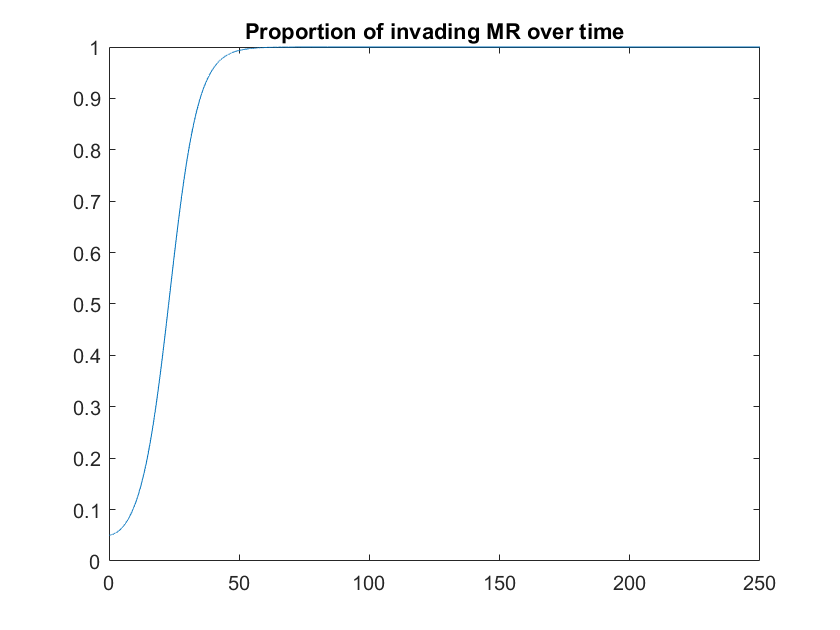

title("Proportion of invading MR over time")

figure
hold on

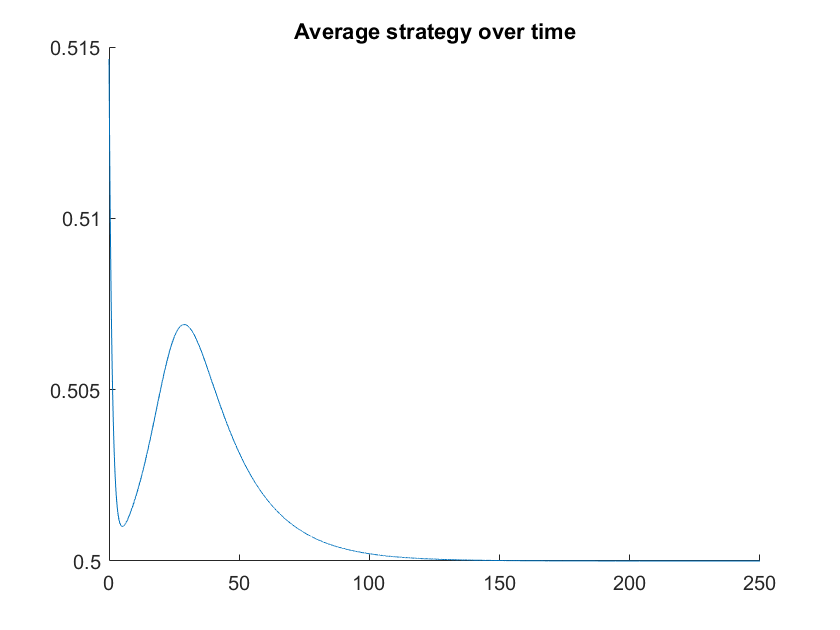

plot(delta_t*(1:max(sample_pts)), avg_strats)
title("Average strategy over time")
hold off
init_dist_res = dist1_record(:,1);
init_dist_inv = dist2_record(:,1);
init_prop_inv = v;

%save("Interesting_avg_strat_curve", 'u_res', 'u_inv', 'init_dist_inv', 'init_dist_res', ...%
%    'init_prop_inv', 'delta_t', 'n_strats',  'spread_matrix_funct')

sometimes we see avg strat decrease before increasing. 

## Verify the results of eigen analysis by block RME

Here we use many resident MR's, and choose the invader delta_u more than the resident. If the proportion of invaders increases after a large amount of time, we can surmise that the invading MR will fixate. 

Elapsed time is 0.275302 seconds.


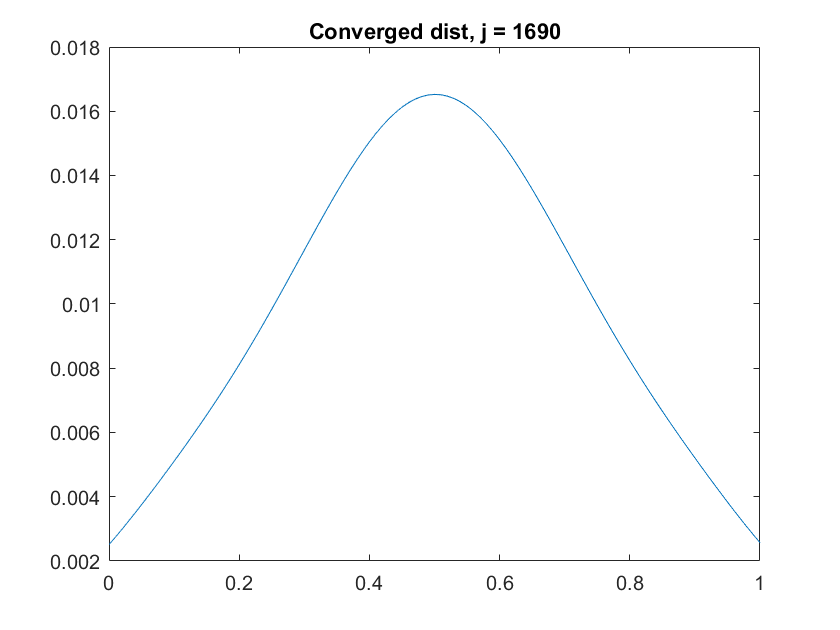

Elapsed time is 6.680424 seconds.


Elapsed time is 0.106414 seconds.


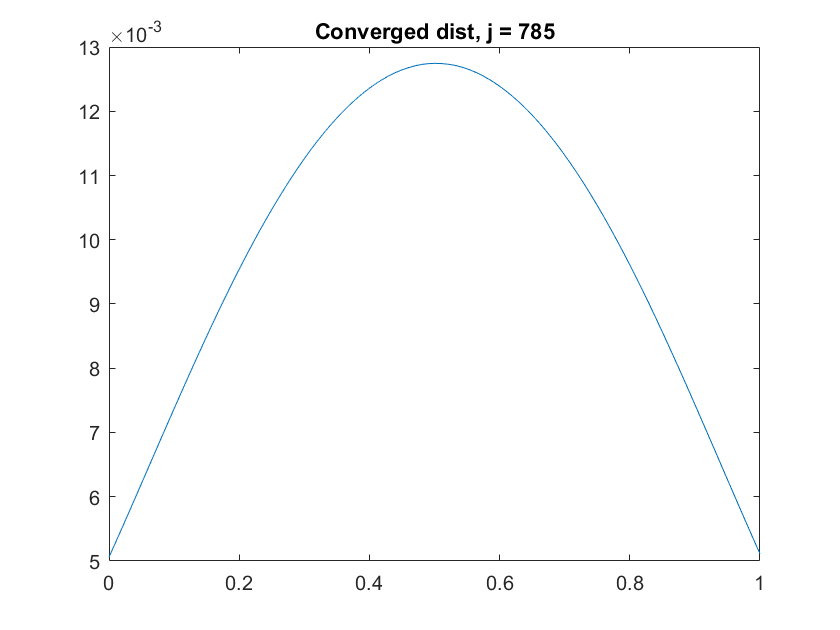

Elapsed time is 3.648783 seconds.


Elapsed time is 0.073245 seconds.


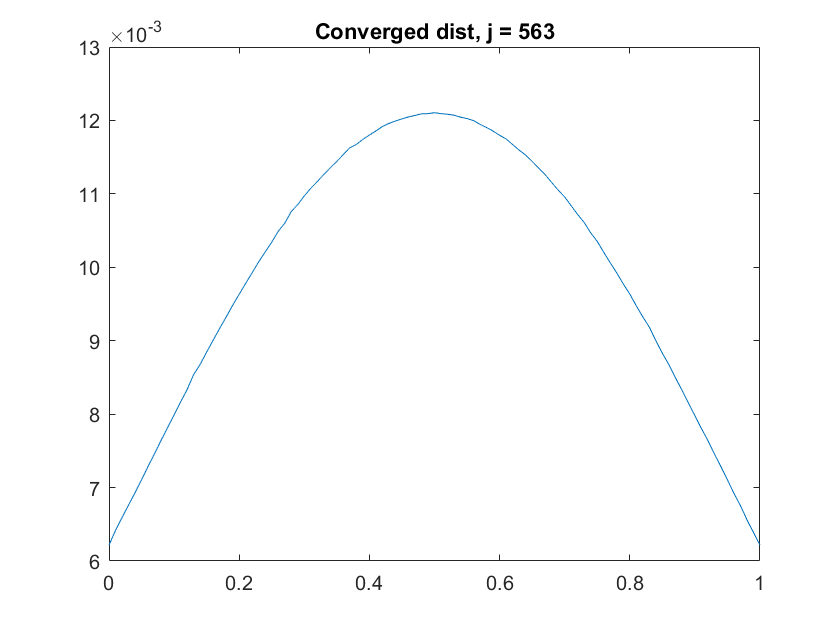

Elapsed time is 3.324789 seconds.


Elapsed time is 0.085043 seconds.


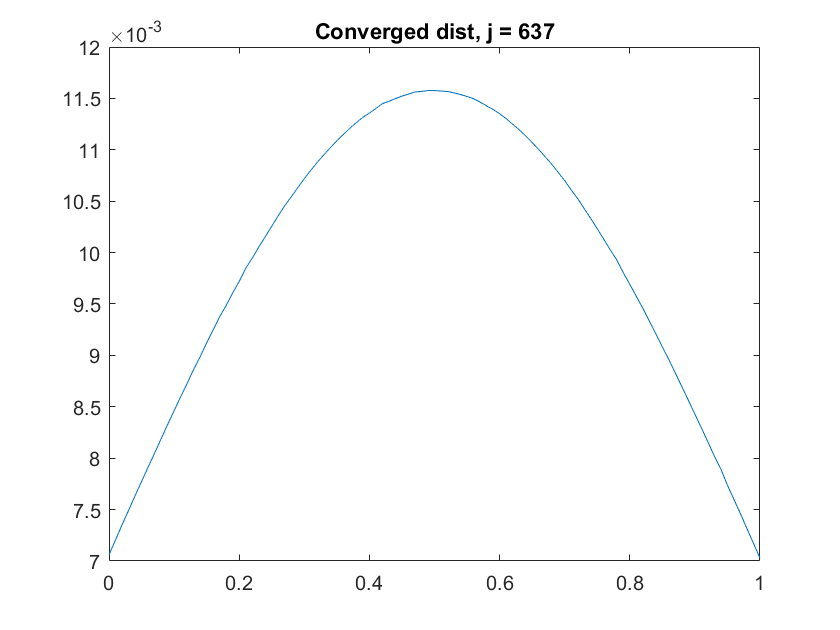

Elapsed time is 3.276515 seconds.


Elapsed time is 0.066044 seconds.


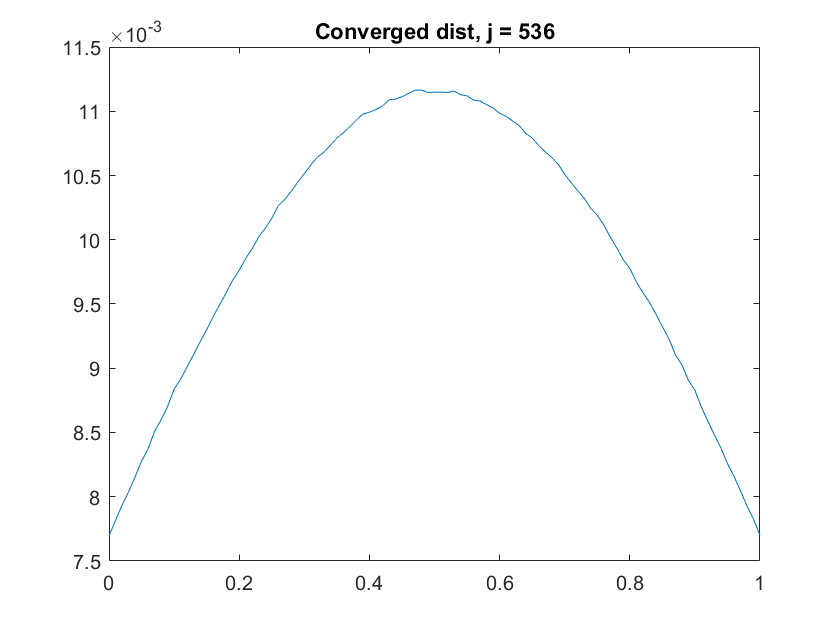

Elapsed time is 3.266410 seconds.


Elapsed time is 0.066354 seconds.


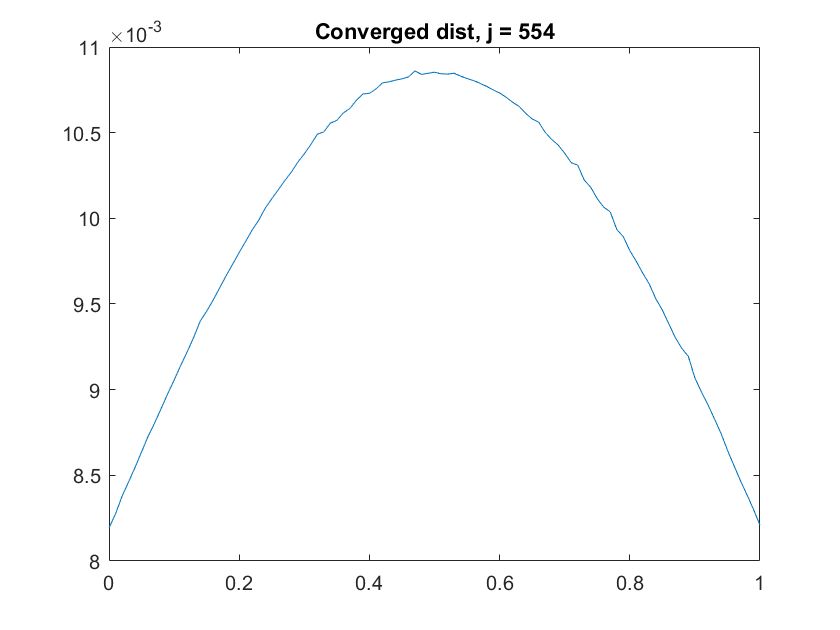

Elapsed time is 3.268874 seconds.


Elapsed time is 0.079387 seconds.


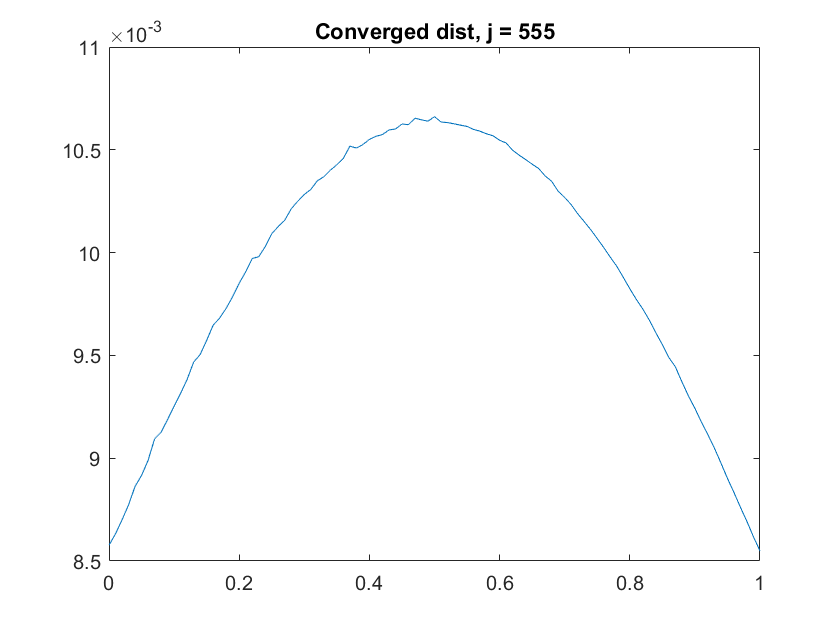

Elapsed time is 3.761775 seconds.


Elapsed time is 0.093202 seconds.


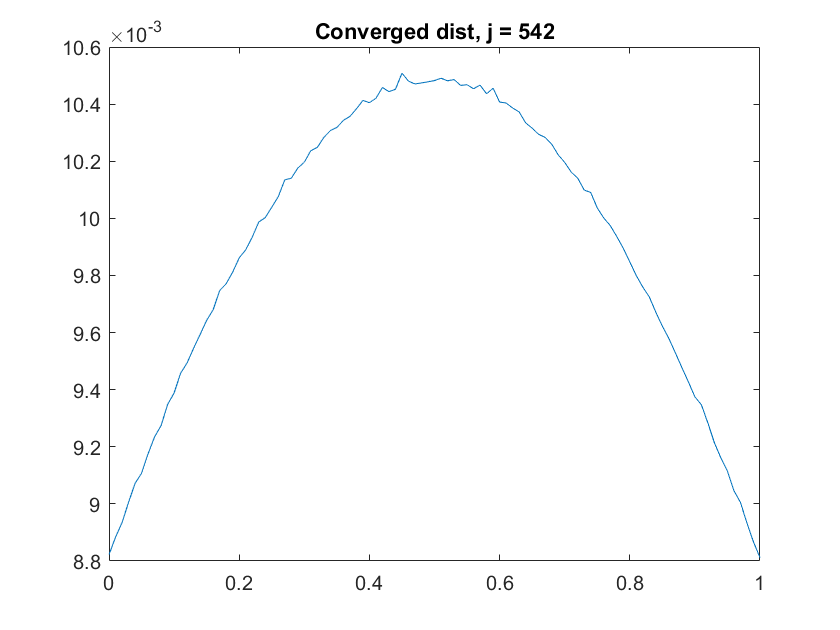

Elapsed time is 3.617368 seconds.


Elapsed time is 0.065676 seconds.


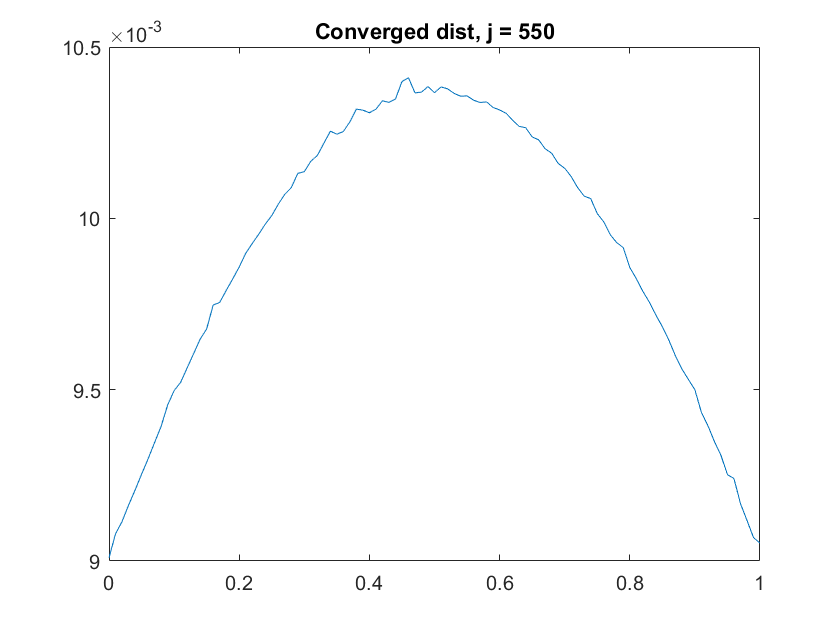

Elapsed time is 3.363953 seconds.


Elapsed time is 0.072552 seconds.


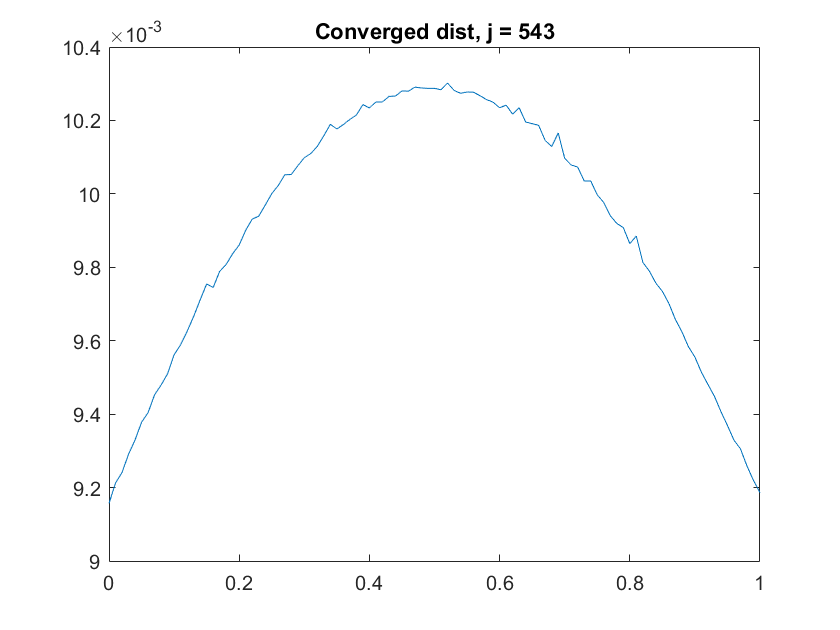

Elapsed time is 3.285874 seconds.


delta_t  = 0.01;
n_steps  = 5000;
tol      = 1e-5; % tolerance to determine when resident is at equilibrium
n_strats = 101;
strats   = linspace(0,1,n_strats);
v = 0.05; % initial proportion of invaders

us   = 0.1*(1:10);
delta_u = 0.01; % u_inv = u_res + delta

final_prop_inv = zeros(1,length(us));
for i=1:length(us)
    tic
    spread_res = spread_matrix_funct(us(i),n_strats);
    dist1 = init(n_strats);
    j = 1;
    dif = 1;
    while dif > tol %&& j < 1000
        % update growth matrix
        growth0 = zeros(n_strats,n_strats);
        growth0(sub2ind(size(growth0), 1:n_strats, 1:n_strats)) = fitness(delta_t*j, dist1, strats);
        
        new_dist1 = advance(dist1, spread_res, growth0, delta_t);
        dif = sum(abs(new_dist1-dist1));
        dist1 = new_dist1;
        j = j + 1;
    end
    toc
    tic
    
    if true
        figure
        plot(strats, dist1);
        title("Converged dist, j = " + j)
    end
    
    dist = [(1-v)*dist1; v*dist1]; % so sum = 1
    
    spread_inv = spread_matrix_funct(us(i)+delta_u,n_strats);
    spread = blkdiag(spread_res, spread_inv);
    
    for k=j:(j+n_steps)        
        % update growth matrix
        sum_dist = dist(1:n_strats)+dist((n_strats+1):end);
        growth0 = zeros(n_strats,n_strats);
        growth0(sub2ind(size(growth0), 1:n_strats, 1:n_strats)) = fitness(delta_t*k, sum_dist, strats);
        growth = blkdiag(growth0, growth0);
    
        dist = advance(dist, spread, growth, delta_t);
    end
    final_prop_inv(i) = sum(dist(n_strats+1:end));
    toc
end

figure
hold on
plot(us, final_prop_inv)
plot(us, v*ones(size(us)), '--')
title("Proportion of invaders after " + delta_t*n_steps + " time units, delta u = " + delta_u)
hold off

## Functions

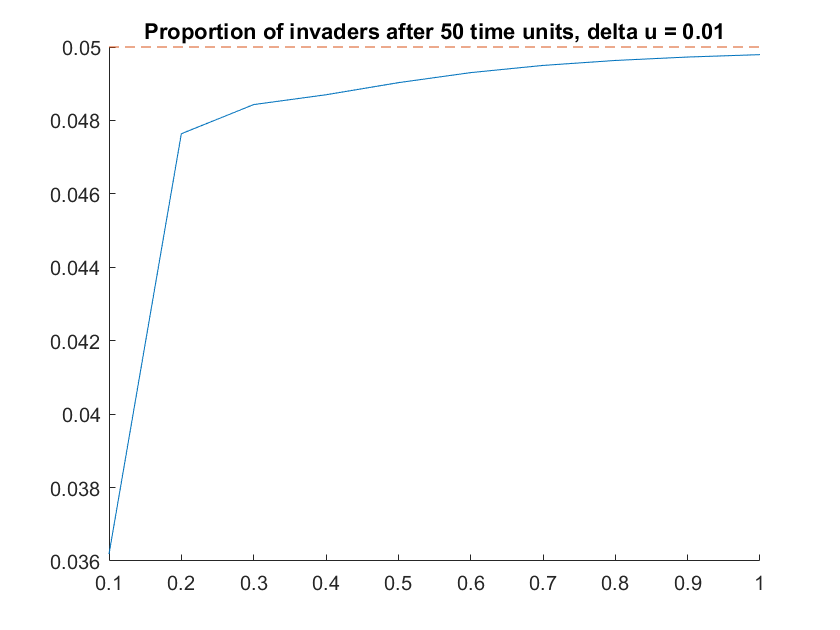

function new_dist = advance(dist, spread, growth, delta_t) 
    dxdt = (spread*growth-sum(growth*dist)*eye(size(growth)))*dist;
    new_dist = dist+delta_t*dxdt;
end

function vals = init(n) % samples uniformly from the simplex, 

    xs = rand(1,n-1);
    xs = sort([0, xs, 1]);
    vals = arrayfun(@(i) xs(i+1)-xs(i), 1:(length(xs)-1))';
end

% Code for the spread matrices
function spread = trunc_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        spread(r,:) = spread_funct(strats, strats(r), u);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = accum_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        vals = spread_funct(linspace(-5,6,11*n), strats(r), u);
        spread(r,:) = vals(1,(5*n+1):6*n); 
        spread(r,1) = spread(r,1) + sum(vals(1, 1:5*n));
        spread(r,n) = spread(r,n) + sum(vals(1, (6*n+1):11*n));

        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        vals = spread_funct(linspace(-2,3,5*n), strats(r), u);
        spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n) + ...
            vals((3*n+1):4*n) + vals((4*n+1):5*n);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = unif_spread_matrix(u,~,n)
    spread = (1-u)*eye(n) + (u/n)*ones(n, n);
end

function spread = integ_accum_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -5, (strats(1)+strats(2))/2);
        for c=2:(n-1)
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 6);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_trunc_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -1/(2*(n-1)), (strats(1)+strats(2))/2);
        for c=2:(n-1) % bin for enpoints goes beyond 0,1 so they are as wide as the others
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 1+1/(2*(n-1)));
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end